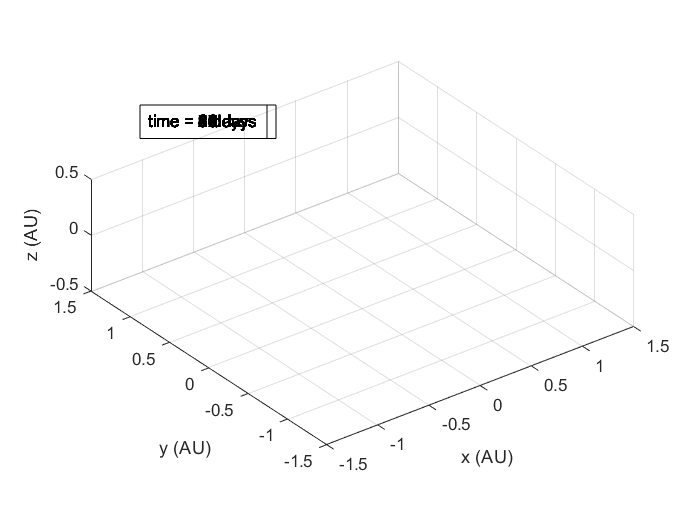

% generates a GIF of orbiting planets based on ephemeris data

h = figure;
axis([-1.5 1.5 -1.5 1.5 -0.5 0.5])
filename = 'orbit.gif';

t_annot_dim = [.2 .5 .3 .3]; % for textbox later
    
earth_path = "earth_transfer_ephem.txt";
mars_path = "mars_transfer_ephem.txt";
[~,x_e,y_e,z_e] = readEphem(earth_path);
[~,x_m,y_m,z_m] = readEphem(mars_path);
   
% create sun
R_sun = 0.004652 * 15; % 15AU
[X_sun, Y_sun, Z_sun] = sphere(50);
X_sun = X_sun.*R_sun;
Y_sun = Y_sun.*R_sun;
Z_sun = Z_sun.*R_sun;

xlabel('x (AU)')
ylabel('y (AU)')
zlabel('z (AU)')

daspect([1 1 1])
view(3)
grid on

tic
for i = 1:50 %1:dt
    %draw plots for planets
    hold on
    earth = plotPlanet(x_e(i),y_e(i),z_e(i),'b');
    mars = plotPlanet(x_m(i),y_m(i),z_m(i),'r');
    sun = surf(X_sun, Y_sun, Z_sun, 'FaceAlpha', 0.9, 'FaceColor', 'y','EdgeColor','none');
    
    %str = strcat("time = ", string(i), " days");
    %annotation('textbox',dim,'String',str,'FitBoxToText','on'); % this is a problem
    
    hold off
    drawnow
    
    
    %capture plot as image
    frame = getframe(h);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
     
    %save image to gif
    if i == 1
        imwrite(imind,cm,filename,'gif','DelayTime', 0.05, 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','DelayTime', 0.05,'WriteMode','append');
    end
    delete(earth);
    delete(mars);
    delete(sun);
end

toc

Elapsed time is 16.466011 seconds.
